# **Metabolic visualisation of Recon3Map with Minerva**

## Authors: Ines Thiele, Ronan M.T. Fleming, Alberto Noronha, 

## **Affiliations: National University of Ireland, Galway; Leiden University; University of Luxembourg.**

## Reviewer(s): 

## INTRODUCTION

The visualisation of metabolic pathways is an essential tool to understand the biological meaning underlying COBRA metabolic models. This would allow the user to visualise what can not be appreciated at first sight by directly looking to the model outputs. Here we present a visualisation through Recon3Map [1] a  visualisation of human metabolism, derived from Recon3 [2], using the Minerva platform [3]. Other human models and maps can be found at the Virtual Metabolic Human [4] website:  [http://www.vmh.life](http://www.vmh.life).

## **EQUIPMENT SETUP**

In order to access remotely to Recon3Map, the user has to be registered. To obtain your credentials, you must access the ADMIN area and request an account.  To access ReconMap follow the link:  [http://www.vmh.life](http://www.vmh.life) .

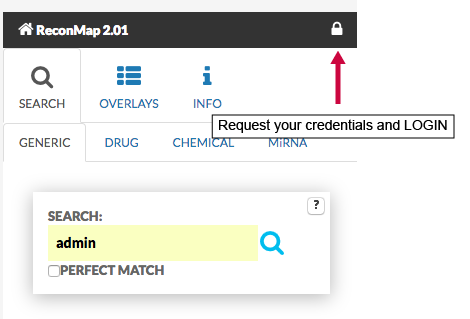     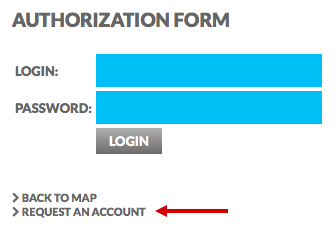

Then, use your credentials to remotely access to [http://www.vmh.life](http://www.vmh.life) 

load('minerva.mat')
minerva.minervaURL = 'http://www.vmh.life/minerva/index.xhtml';
minerva.map = 'ReconMap-3';
if 0
    minerva.login = 'user_name';
    minerva.password = 'user_password';
else
    minerva.login = 'ronan.fleming';
    minerva.password = 'ronan.fleming1';
    %minerva.login = 'cobratoolbox-test';
    %minerva.password = 'test';
end
minerva.googleLicenseConsent = 'true';

Initialise the Cobra Toolbox.

A specific solver might be required (depending on the analysis you want to realise in the COBRA model).

changeCobraSolver('ibm_cplex','QP');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.


changeCobraSolver('ibm_cplex', 'LP');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.


Load your generic metabolic model. Recon's most recent version "Recon2.04" can be freely downloaded from [http://www.vmh.life](http://www.vmh.life)  

model = load('Recon3DModel_301.mat')

model = struct with fields:
    model: [1×1 struct]

if isfield(model,'model')
    model=model.model;
end

## **PROCEDURE**

**1. Overlay a flux distribution**

As an example of layout, we would like to see the the fluxes when maximizing ATP production  through complex V (ATP synthase) in the Electron Transport Chain. To do so, we use Flux Balance Analysis (FBA) and set as an objective function the reaction responsible of this process (`'ATPS4m'). `

`ChangeObjective `function, changes the objective function of a constraint-based model 

`optimizeCbModel `function solves a flux balance analysis problem.

formula = printRxnFormula(model, 'ATPS4mi')

ATPS4mi	adp[m] + pi[m] + 4 h[i] 	->	h2o[m] + 3 h[m] + atp[m] 


formula = 1×1 cell array
    {'adp[m] + pi[m] + 4 h[i]  -> h2o[m] + 3 h[m] + atp[m] '}


model_atp_production = model  % re-name the model to do not modify the original one.

model_atp_production = struct with fields:
                      S: [5835×10600 double]
                   mets: {5835×1 cell}
                      b: [5835×1 double]
                 csense: [5835×1 char]
                   rxns: {10600×1 cell}
                     lb: [10600×1 double]
                     ub: [10600×1 double]
                      c: [10600×1 double]
                 osense: -1
                  genes: {2248×1 cell}
                  rules: {10600×1 cell}
             metCharges: [5835×1 int64]
            metFormulas: {5835×1 cell}
              metSmiles: {5835×1 cell}
               metNames: {5835×1 cell}
              metHMDBID: {5835×1 cell}
         metInChIString: {5835×1 cell}
              metKEGGID: {5835×1 cell}
           metPubChemID: {5835×1 cell}
            description: 'Recon3DModel.mat'
                grRules: {10600×1 cell}
             rxnGeneMat: [10600×2248 double]
    rxnConfidenceScores: [10600×1 double]
               rxnNames: {10600×1 ce

model_atp_production = changeObjective(model_atp_production, 'ATPS4mi'); 

Regularised flux balance analysis

solution_atp_prod_max_regularised = optimizeCbModel(model_atp_production, 'max',1e-6);

Sparse flux balance anaysis

solution_atp_prod_max_sparse = optimizeCbModel(model_atp_production, 'max','zero');

This reaction, (S)-2-Methylbutanoyl Coenzyme A:Acceptor 2, 3-Oxidoreductase Valine, Leucine And Isoleucine Degradation ('r0603') is expressed in the regularised flux balance analysis solution, but not in the sparse flux balance analysis solution.

formula = printRxnFormula(model, 'r0603');

r0603	2mbcoa[m] + q10[m] 	->	2mb2coa[m] + q10h2[m] 



nnz(solution_atp_prod_max_regularised.v)

ans = 10600

solution_atp_prod_max_regularised.v(strcmp(model.rxns,'r0603'))

ans = 2.3688


nnz(solution_atp_prod_max_sparse.v)

ans = 41

solution_atp_prod_max_sparse.v(strcmp(model.rxns,'r0603'))

ans = 0

## ANTICIPATED RESULTS

`The buildFluxDistLayout `function creates a layout that is automatically sent to the ReconMap website. After this, you can visualise your layout in [http://www.vmh.life](http://www.vmh.life). Use your credentials to log in as it is previously explained.  Select your input map (minerva.model) and go to "overlays" section to find your layout.   

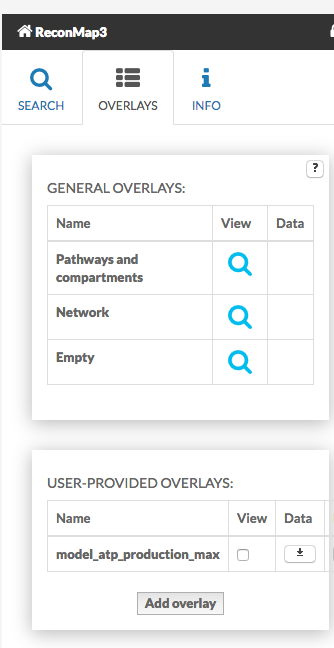

serverResponse = buildFluxDistLayout(minerva, model, solution_atp_prod_max_sparse, 'atp_prod_max_sparse_2020','#6617B5')

Overlay generated successfully.


serverResponse = 'Overlay generated successfully.'

%TODO
% why does this does not work at present?
% perhaps because the size of the curl post is too large?
if 0
    serverResponse = buildFluxDistLayout(minerva, model, solution_atp_prod_max_regularised, 'atp_prod_max_2020','#6617B5')
end

If everything is correctly defined you should get a structure with 2 values. If everything works fine, the output of this function should be:

`[1] 'Overlay generated successfully.' `

 If there is any error, the message obtained will display:

`[0] 'Overlay NOT generated successfully.' `

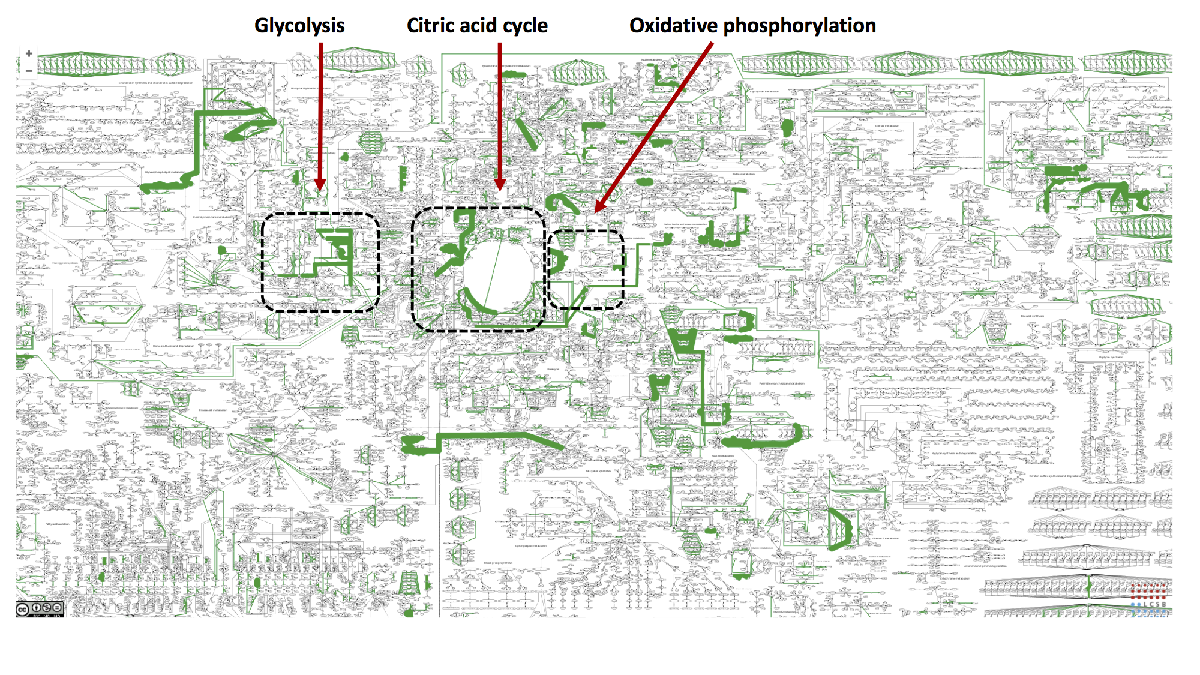

Note: If the "layout name" selected has been already given, an error might appear. Please, try to give a new layout name each time you run the code. 

`[0]    'ERROR. Layout with given identifier ("atp_productio…'`

**2. Overlay a SubSystem**

There is also the possibility to highlight a specific subSystems by using the function `generateSubsytemsLayout. A` subSystem is a group of metabolic reactions involved in the same metabolic pathway, such as glycolysis, Oxidative phosphorylation, citric acid cycle, etc.  Add the name of a specific subSystem you want to highlight from the COBRA model (see the example, TCA cycle), and the color reference. 

generateSubsytemsLayout(minerva, model, 'Citric acid cycle', '#6617B5');

Overlay generated successfully.


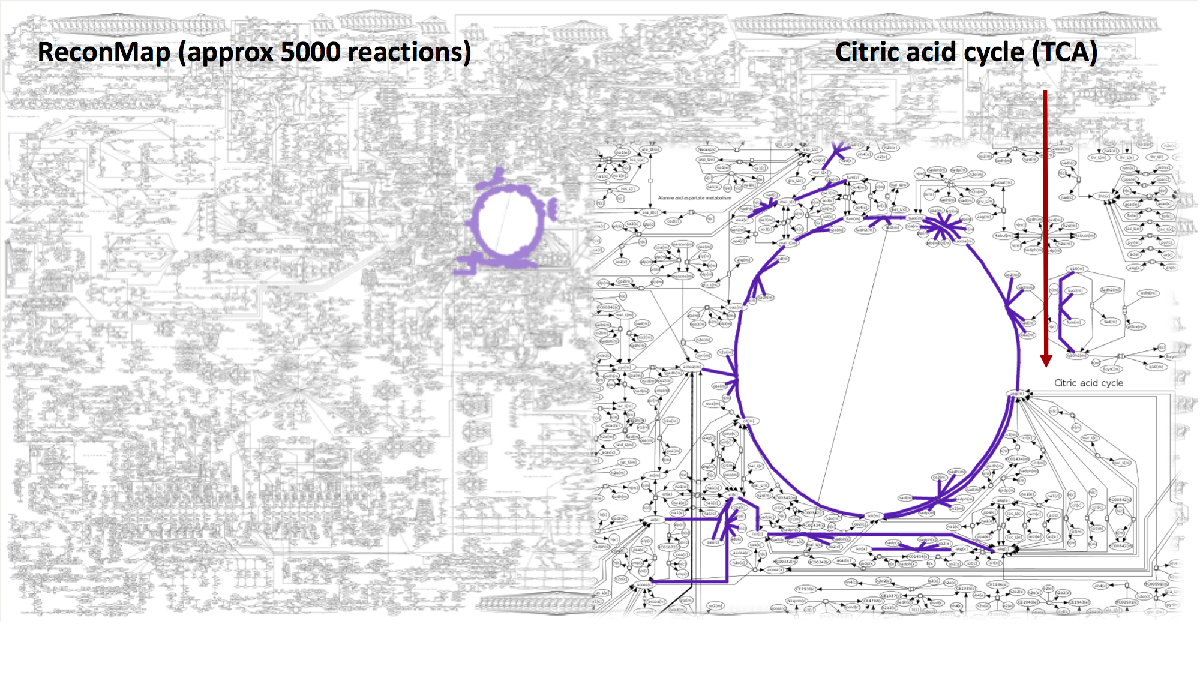

Alternatively, the user can generate a layout of all common subSystems between model and map using the function  `generateSubsystemLayouts. `

Note: every single layout can be observed individually, or merged with other layouts. Therefore, making possible the visualization of several layouts at the same time.

**RECONMAPS**

There is an additional set of maps available in VMH consistent with the content of Recon 3D [3]. ReconMap3 is the general map that follows the same approach as the previous iteration, but we have also included 6 organelle-specific maps. You can see each of these by clicking on the corresponding button on the interface as shown below.

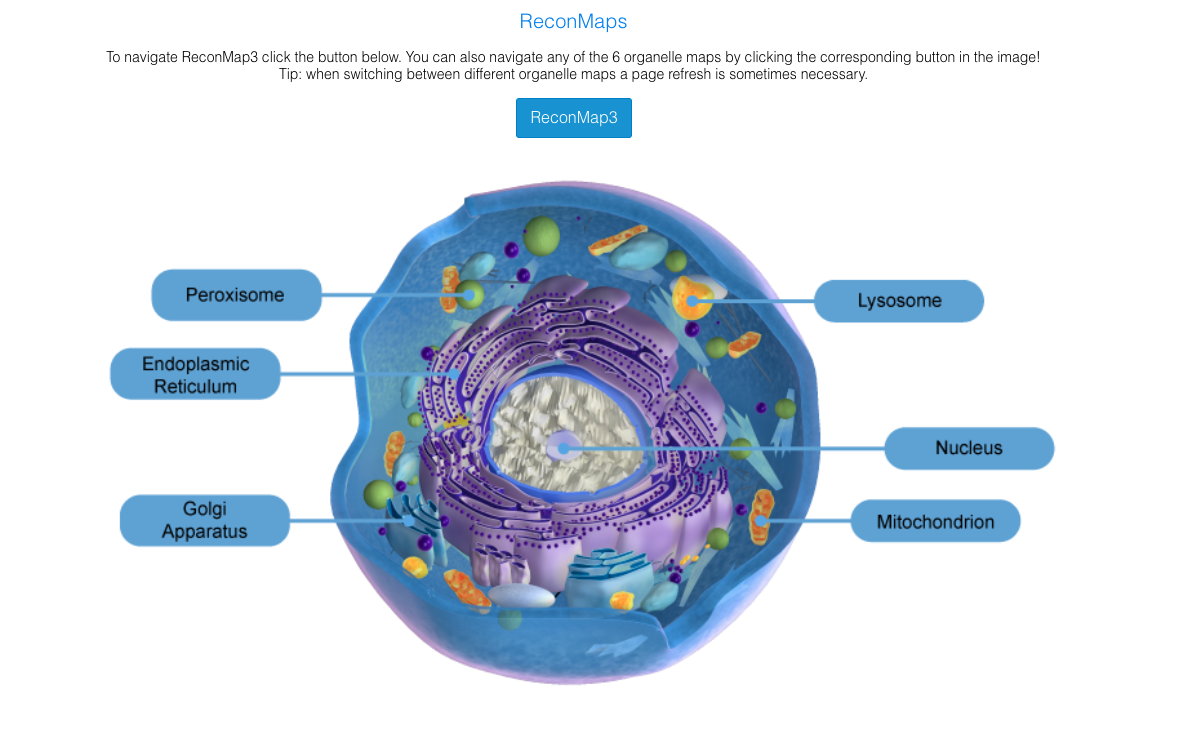

To submit flux distributions to specific maps, users just need to change the map variable from the minerva struct with the identifier of the desired map using one of the lines of code displayed below:

minerva.map = 'ReconMap-3'; % ReconMap 3
minerva.map = 'reticulum'; % Endoplasmic reticulim map
minerva.map = 'peroxisome'; % Peroxisome map
minerva.map = 'nucleus'; % Nucleus map
minerva.map = 'mitochondrion'; % Mitochondrion map
minerva.map = 'lysosome'; % Lysosome map
minerva.map = 'golgi'; % Golgi apparatus map

## **3. Manual upload of overlays**

It is also possible to manually submit your overlays. For this purpose, you can generate a tab delimited file with the necessary information using the `printInRecon3Dmap` function.

%function printInRecon3Dmap(rxnList, colorValues, outputDir)
% This function generates a TXT file that can be integrated in the VMH
% database (vmh.life) to overlay certain reactions 

**Overlay File format:**

To upload reaction fluxes in Recon2Map use the following tab delimited format:

name    reactionIdentifier    lineWidth    color

    HEX1    2    #57c657

If you are uploading a file to Recon3Map3 and newer versions, it is necessary to add a prefix "R_" to each reaction identifier. 

name    reactionIdentifier    lineWidth    color

    R_HEX1    2    #57c657

**Steps to upload an Overlay File:**

- **Login** to  [https://www.vmh.life/#reconmap](https://www.vmh.life/#reconmap) with the same credentials as used above.

- Select** Overlays > User-provided overlays** section 

- Select **Add overlay** 

- Select **Choose File** to navigate to a local file to uploa.

Note: To see uploaded overlay agree to the Google Maps terms.

For more information on MINERVA's functionalities check MINERVA' manual at: [https://minerva.pages.uni.lu/doc/](https://minerva.pages.uni.lu/doc/)

## REFERENCES: 

[1] Alberto Noronha, Anna Dröfn Daníelsdóttir, Piotr Gawron, Freyr Jóhannsson, Sofía Jónsdóttir, Sindri Jarlsson, Jón Pétur Gunnarsson, Sigurður Brynjólfsson, Reinhard Schneider, Ines Thiele, and Ronan M. T. Fleming. ReconMap: an interactive visualization of human metabolism. Bioinformatics , 33(4):605607, February 2017.

[2] Elizabeth Brunk, Swagatika Sahoo, Daniel C Zielinski, Ali Altunkaya, Andreas Dräger, Nathan Mih, Francesco Gatto, Avlant Nilsson, German Andres Preciat Gonzalez, Maike Kathrin Aurich, Andreas Prlić, Anand Sastry, Anna D Danielsdottir, Almut Heinken, Alberto Noronha, Peter W Rose, Stephen K Burley, Ronan M T Fleming, Jens Nielsen, Ines Thiele & Bernhard O Palsson. Recon3D enables a three-dimensional view of gene variation in human metabolism. *Nature Biotechnology* volume 36, pages 272–281 (2018)

[3] P. Gawron, M. Ostaszewski, V. Satagopam, S. Gebel, A. Mazein, M. Kuzma, S. Zorzan, F. McGee, B. Otjacques, R. Balling, and R. Schneider “MINERVA—a platform for visualization and curation of molecular interaction networks” in npj Systems Biology and Applications, vol. 2, p. 16020, Sep. 2016, doi:10.1038/npjsba.2016.20.

[4] Noronha et al., "The Virtual Metabolic Human database: integrating human and gut microbiome metabolism with nutrition and disease", Nucleic Acids Research (2018); [https://academic.oup.com/nar/advance-article/doi/10.1093/nar/gky992/5146204](https://academic.oup.com/nar/advance-article/doi/10.1093/nar/gky992/5146204)